# splWindows

A script to calculate a lobing pattern of tonal and broadband sound pressure level measurements at an array of hydrophones from a passing ship using its AIS track. By grouping all of the consecutive measurements along the ships track by same look angle (azimuth), the lobing characteristics of the ship's noise signature can be estimated. 

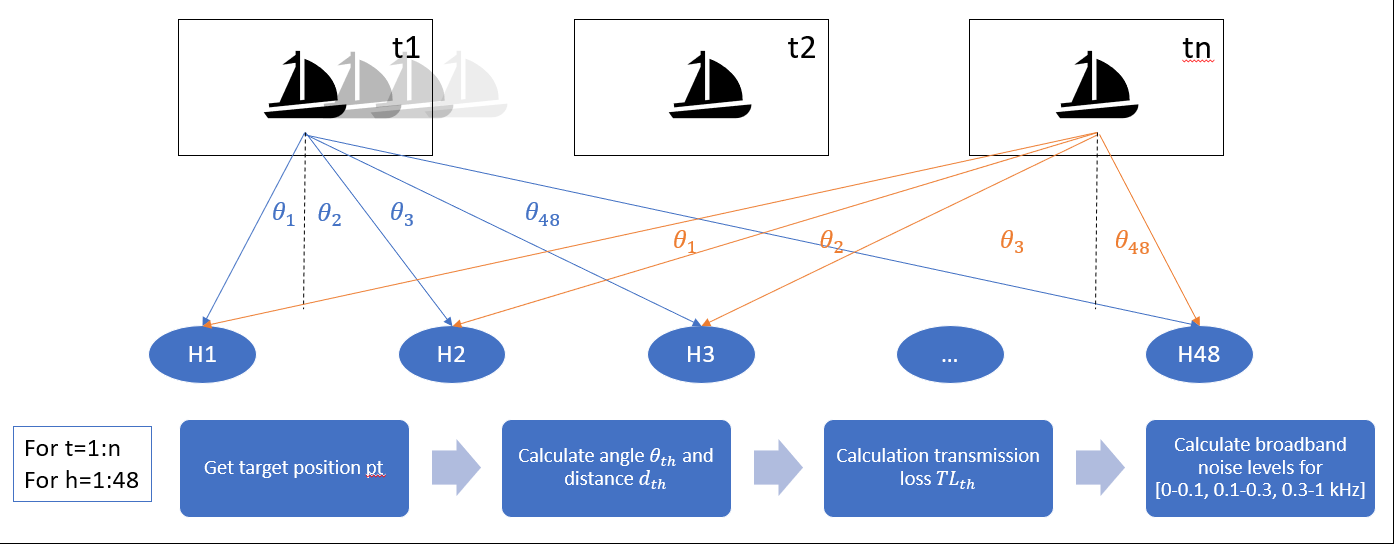

## Initialize & set parameters

clearvars
load arrays_lat-long
array1=table2array(array1(:,1:2));
array2=table2array(array2(:,1:2));

Num1secSeg = 5;                             %number of segments for averaging
TimeIntSec = 3;                             %time-difference [sec] btw. beginning of segments
fstartind = 10;                             %10Hz for computing received levels
fstopind = 1001;                            %1000Hz for computing received levels
NumRec = 2; %48;                                %Number of recorder channels
BinWidth = 1;                               %Bin Width [Hz] 

## Acoustic data pre-processing

### Define parameters

sens = 194.5;  % (nominal) dB re 1V/uPa
cal = 10^(sens/20); 
%gain = 70;   % Amplifier gain 70 dB (adjustable), A/D -8 dB (I don't think gain is correct - confirm A/D)
adc = 5/(2^16); % 1 Vrms = 16 bit peak-to-peak --> could also be +/- 1 floating point range (20log(2.0/5.0))

### Load acoustic data

dFile = 'allCh.wav';           % Select the 48-ch (allCh) or 1-ch (singleCh) file
%NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\HebSky\proc',dFile);
%NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150830_AAA2\proc',dFile);
NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150830_AAA2\west_aaa2_20150830_094520_00_0010.wav');
[x,fs] = audioread(NWFile);  % What is this signal? Volts? --> need to convert to dB (x/sens)
SegLengthSamples = BinWidth*fs; 
DataLengthSamples = Num1secSeg*SegLengthSamples;
%x = x/cal;

### Downsample acoustic data (optional)

sampling = 'full'; %'downsample'; % or 'full'

switch sampling
    case 'full' 
        nFactor = 1;
        disp('sampling full band')
    case 'downsample'
        nFactor = 1000;
        y = downsample(x,nFactor); %downsample or decimate?
        x = y; 
        clear y
end

sampling full band


[nsam,nch] = size(x);

### Generate time vector

%t = cumsum(ones(length(x(:,1))/fs,1)); % time vector in seconds
%t = seconds(t*nFactor);
% %startTime = datetime(2015,8,26,16,59,58);  % HebSky - west_aaa2_20150826_165958_00_0131
startTime = datetime(2015,8,30,9,17,24);  % OcEnd - west_aaa2_20150830_091724_00_0007
StartTime = datenum(startTime);
endTime = startTime + seconds(length(x(:,1))/fs);  % length(x)/fs = 
EndTime = datenum(endTime);
TimeVector = StartTime:TimeIntSec/(3600*24):EndTime;
%t = t + startTime;
%TimeVector = datenum(t);
%StartTime = datenum(startTime);
%EndTime = datenum('08/30/2015 09:17:24');
%TimeVector = StartTime:TimeIntSec/(3600*24):EndTime;    %1x601
NumSpec = length(TimeVector);                           %601

### Transfer function for array

One-sided to save memory

fRspectra = fs/2*linspace(0,1,SegLengthSamples/2+1); %frequencies [Hz]
% G = 10^(sens/20)*ones(length(fRspectra),1);
G = 10^(sens/20);

## Received Spectra with 1 Hz bins

Paper: Each of the eight pressure time series was divided into consecutive, non-overlapping segments with a length of 1 s (200 000 samples).

S =  cell(NumRec,1);   % Spectra for each array elements
for RecInd=1:NumRec
    S{RecInd} = zeros(NumSpec-2,SegLengthSamples/2+1);  % 48 x fs  (one-sided)
end

### Loop to read data piece by piece

for EventIndex = 1:(NumSpec-2)
    for RecInd=1:NumRec   
        data = x(TimeIntSec*fs*(EventIndex-1)+1:...
         TimeIntSec*fs*(EventIndex-1)+DataLengthSamples,RecInd);
        NumSeg = floor(length(data)/SegLengthSamples);
        %FileIndex = ...
            %find((xwavReferenceTime{RecInd}(:) - TimeVector(EventIndex))<0);
            %%need to find a way to handle partial segments
%         StartSample = round(fs*(TimeVector(EventIndex) - ...
%                     StartTime)*(24*3600)); 
%         data = MTRead(filename{RecInd}{FileIndex(end)},...
%                     StartSample,StartSample+DataLengthSamples(RecInd)-1,'p');    
         %data=data.';

### Compute received spectra

Paper: A two-sided Fast Fourier Transform (FFT) with NFFT=200 000 points was applied to each segment to yield a frequency bin spacing of 1 Hz. The magnitude squared values of the complex FFT coefficients for the positive frequencies were multiplied by 2/NFFT^2 to account for the processing gain of the FFT.

Compute onesided spectra and calibrate with HARP specific hydrophone transfer functions

%         for SegInd=1:NumSeg  
%             X = fft(data(:,SegInd));
%             S{RecInd}(EventIndex,:) = S{RecInd}(EventIndex,:) + ...
%                         (((2*abs(X(1:SegLengthSamples/2+1,:)).^2)*G^2)...
%                         /(SegLengthSamples*fs)).';         
%         end
    
    X = fft(reshape(data(1:NumSeg*SegLengthSamples),...
                SegLengthSamples,NumSeg));
            %compute onesided spectra and calibrate with HARP specific hydrophone transfer functions
            S{RecInd}(EventIndex,:) = ...
                (sum(2*abs(X(1:SegLengthSamples/2+1,:)).^2,2)*G^2)...
                /(NumSeg*SegLengthSamples*fs);        
    end
        
    %display progress
    if mod(EventIndex,round(NumSpec/10))==0
        disp([num2str(round(100*EventIndex/NumSpec)) '% done'])   
    end
end

10% done
20% done
30% done
41% done
51% done
61% done
71% done
81% done
91% done


gain = -78;   % Amplifier gain -70 dB (adjustable), A/D -8 dB (I don't think gain is correct - confirm A/D)

### Plot Spectrograms

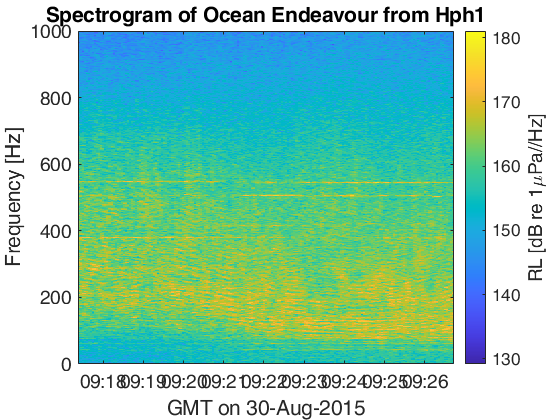

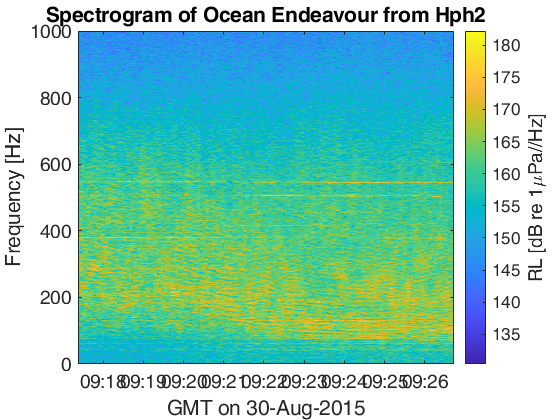

FontSizeNumber=14;
for RecInd=1:NumRec
figure;
    %RecInd = RefRecInd;    
    imagesc(TimeVector,fRspectra,10*log10(S{RecInd}).');
    title(['Spectrogram of Ocean Endeavour from Hph' num2str(RecInd)],'FontSize',FontSizeNumber)
    axis xy; 
    h = colorbar;%caxis([50 130])
    set(get(h,'ylabel'),'string','RL [dB re 1\muPa//Hz]',...
        'FontSize',FontSizeNumber);
    datetick('x','keeplimits');
    xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')],...
        'FontSize',FontSizeNumber)
    ylabel('Frequency [Hz]','FontSize',FontSizeNumber)
    ylim([0 1000])
    set(gca, 'FontSize',FontSizeNumber)
end

## Plot Average Spectra

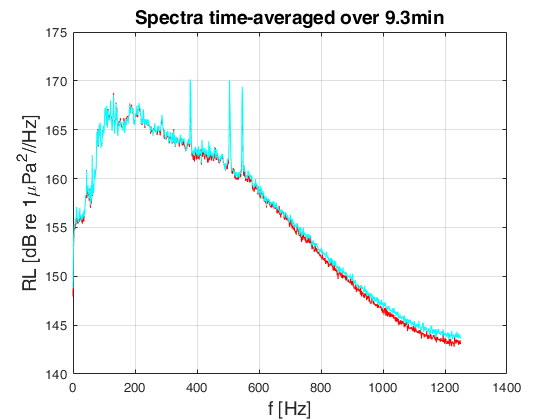

figure; 
NumLinesPlot = 2;
NumSubPlots = ceil(NumRec/NumLinesPlot);
colorarray = hsv(NumRec);
for RecInd=1:NumRec
    SubPlotInd = floor(RecInd/(NumLinesPlot+1))+1;
    if RecInd == 7 
        SubPlotInd = 3; 
    end
    subplot(NumSubPlots,1,SubPlotInd)
        plot(fRspectra,10*log10(sum(S{RecInd})/NumSpec),...
            'Color',colorarray(RecInd,:));
        hold on
        %ylim([60 130])
        %xlim([5 100])
        grid on        
        if SubPlotInd == 1
            title(['Spectra time-averaged over '...
                num2str((TimeVector(end)-TimeVector(1))*24*60) 'min'],'FontSize',FontSizeNumber)
        end            
        ylabel('RL [dB re 1\muPa^2//Hz]','FontSize',FontSizeNumber)
        xlabel('f [Hz]','FontSize',FontSizeNumber)
end

## Spatial data processing

### Load AIS file

m = matfile('byShip.mat');
AIS = m.Oc_End; %m.Heb_Sky;
AIS = sortrows(AIS,'datetime','ascend');
mmsi = AIS.mmsi(1); 
AIS.mmsi = []; AIS.rate_of_turn = []; AIS.hdg = [];  % eliminate unused vars
AIStime = table2timetable(AIS);  % might need to make all of this a structure
AIStimeRange = timerange((startTime-minutes(3)),(endTime+minutes(3)))
AIStime = AIStime(AIStimeRange,:);

NumAISlocs = length(AIS.time);

%map AIS lats/longs to x-y    
[AIS.x, AIS.y] = latlon2xy(AIS.lat,AIS.long,...
        CINMS_B_30(RefRecInd).lat,CINMS_B_30(RefRecInd).long);


### Calculate ranges along ship track

[R1,R2] = calcDist(AIS.lat, AIS.long, array1, array2);
AIStime = addvars(AIStime,R1,R2);

### Calculate CPA range and time

[rangeCPA_1,timeCPA_1] = min(R1(:,1,1));
[rangeCPA_2,timeCPA_2] = min(R2(:,1,1));
specCPA = 'CPA range AAA1 = %4.2f km and AAA2 = %4.2f km';
fprintf(specCPA,rangeCPA_1,rangeCPA_2); 

### Plot bearing histogram of ranges

rangeRoser(R2(:,1,2), R2(:,1,1), 'legendtype', 1, 'anglenorth', 0, 'angleeast', 90, 'lablegend', 'Distance (km)');
set(gca,'FontSize',14);

### Plot time resolution of AIS data, speed and range history of contact

figure
subplot(3,1,1)
    plot(AIS.datetime(1:end-1),diff(AIS.datetime),'.');
    datetick('x')
    ylabel('\DeltaT [sec]')    
subplot(3,1,2)
    plot(AIS.datetime,AIS.speed_over_ground,'.');
    datetick('x')
    ylabel('Ship speed [m/s]') 
subplot(3,1,3)
    plot(AIS.datetime,R1(:,1,1),'.');
    hold on
    plot(AIS.datetime,R2(:,1,1),'-')
    datetick('x')
    ylabel('Contact range (km)')  
    legend('Array 1','Array 2')

### Calculate TL for each window location

AIStime.TL1 = 10*log(R1(:,:,1)*1000);
AIStime.TL2 = 10*log(R2(:,:,1)*1000);  

### Find ship passage in AIS data (give +/- 3 min extra time for smoothing)

m = matfile('byShip.mat');
AIS = m.Oc_End; %m.Heb_Sky;
AIS = sortrows(AIS,'datetime','ascend');

AIS = findShips(Ship,[StartTime-(3/(60*24)) EndTime+(3/(60*24))],[],MMSI);
AIS = AIS{1};
NumAISlocs = length(AIS.time);

%map AIS lats/longs to x-y    
[AIS.x, AIS.y] = latlon2xy(AIS.lat,AIS.long,...
        CINMS_B_30(RefRecInd).lat,CINMS_B_30(RefRecInd).long);

%fix potential errors of time stamp due to AIS computer clock drift
%==================================================================

%determine closest point of approach by finding the maximum RL at propeller blade line
PropFreqLineInd = 6; %8Hz  blade rate fundamental (orginates from propeller)
PropCPAInd = zeros(NumRec,1);
AISCPAInd = zeros(NumRec,1);
for RecInd=1:NumRec
    [~,PropCPAInd(RecInd)]=max(S{RecInd}(:,PropFreqLineInd));
    [~,AISCPAInd(RecInd)]=min((AIS.x-CINMS_B_30SelArr(RecInd,1)).^2 + (AIS.y-CINMS_B_30SelArr(RecInd,2)).^2);
end    
[PropCPAInd AISCPAInd (TimeVector(PropCPAInd)-AIS.time(AISCPAInd)).'*24*60]

%determine correct draft
[~,DraftIndex] = min(abs((StartTime+(EndTime-StartTime)/2) - AIS.DraftDay));

%plot AIS data
h=plotShips({AIS},1);
FontSizeNumber=16;
set(gca, 'FontSize',FontSizeNumber)
xlabel('Eastings [km]','FontSize',FontSizeNumber)
ylabel('Northings [km]','FontSize',FontSizeNumber)    
set(gca,'XTick',[-6:3:6])

%plot time-resolution of AIS data
figure;
    subplot(2,1,1)
    plot(AIS.time(1:end-1),diff(AIS.time*24*3600),'.');
    datetick('x')
    ylabel('\DeltaT [sec]')    
subplot(2,1,2)
    plot(AIS.time,AIS.speed,'.');
    datetick('x')
    ylabel('Ship speed [m/s]')
    xlabel('HH:MM')    
    
%compute ship length and width
AIS.length = AIS.GPS2bow + AIS.GPS2stern;
AIS.width = AIS.GPS2port + AIS.GPS2stbd;    

% ISO 17208-1:2016(E): 1/4 of ship length away from stern
AIS.GPS2RefPoint.ISO = [AIS.width/2-AIS.GPS2port AIS.length/4-AIS.GPS2stern];

% ANSI/ASA S12.64-2000: halfway between propeller and engine room
AIS.GPS2RefPoint.ANSI = [AIS.width/2-AIS.GPS2port Stern2EngRoom/2-AIS.GPS2stern];

%Interpolate ship location & speed at the time stamps of the acous. spectra  
MaxAISdt = Inf;%65/(3600*24); % [decimal days]
AIS.xint = zeros(1,NumSpec);
AIS.yint = zeros(1,NumSpec);
AIS.speedint = zeros(1,NumSpec);
AIS.xintISO = zeros(1,NumSpec);
AIS.yintISO = zeros(1,NumSpec);
AIS.xintANSI = zeros(1,NumSpec);
AIS.yintANSI = zeros(1,NumSpec);

warning('off')
for TimeInd=1:NumSpec
    [dt dtInd] = min(abs(AIS.time-TimeVector(TimeInd)));
        if dt < MaxAISdt
            if dtInd >= 3 && dtInd <= NumAISlocs-2
                p.x = polyfit(AIS.time(dtInd-2:dtInd+2),AIS.x(dtInd-2:dtInd+2),1);
                AIS.xint(TimeInd) = polyval(p.x,TimeVector(TimeInd));                 
                p.y=polyfit(AIS.time(dtInd-2:dtInd+2),AIS.y(dtInd-2:dtInd+2),1);
                AIS.yint(TimeInd) = polyval(p.y,TimeVector(TimeInd)); 
                p.s = polyfit(AIS.time(dtInd-2:dtInd+2),AIS.speed(dtInd-2:dtInd+2),1);
                AIS.speedint(TimeInd) = polyval(p.s,TimeVector(TimeInd));
                
                rotangle.x = atan(p.x(1));
                rotangle.y = atan(p.y(1));
                
                % ISO 17208-1:2016(E): 1/4 of ship length away from stern
                AIS.xintISO(TimeInd) = AIS.xint(TimeInd) ...
                    + cos(rotangle.x).*AIS.GPS2RefPoint.ISO(1) + sin(rotangle.y)*AIS.GPS2RefPoint.ISO(2);
                AIS.yintISO(TimeInd) = AIS.yint(TimeInd) ...
                    -sin(rotangle.x)*AIS.GPS2RefPoint.ISO(1) + cos(rotangle.y)*AIS.GPS2RefPoint.ISO(2);

                % ANSI/ASA S12.64-2000: halfway between propeller and engine room
                AIS.xintANSI(TimeInd) = AIS.xint(TimeInd) ...
                    + cos(rotangle.x).*AIS.GPS2RefPoint.ANSI(1) + sin(rotangle.y)*AIS.GPS2RefPoint.ANSI(2);
                AIS.yintANSI(TimeInd) = AIS.yint(TimeInd) ...
                    -sin(rotangle.x)*AIS.GPS2RefPoint.ANSI(1) + cos(rotangle.y)*AIS.GPS2RefPoint.ANSI(2);                
            end
        else
            %longer gaps in the AIS data
            disp([datestr(TimeVector(TimeInd)) ': AIS data gap > '...
                num2str(MaxAISdt) 'sec.'])  
        end    
end    
warning('on')

switch ShipStandard 
    case 'ANSI'
        AIS.xint = AIS.xintANSI;
        AIS.yint = AIS.yintANSI;
        disp('Ship locations computed for Ship Reference Point according to ANSI/ASA.')
    case 'ISO'
        AIS.xint = AIS.xintISO;
        AIS.yint = AIS.yintISO;
        disp('Ship locations computed for Ship Reference Point according to ISO.')
    case 'GPS'    
        disp('Ship locations computed for Ship Reference Point according to GPS antenna location.')
end        
    
%% Compute Speed vectors from track
%needed for computing the radiation pattern

%speed from interpolated AIS track
AIS.vx = diff(AIS.xint)./(diff(TimeVector)*24*3600); %m/s
AIS.vy = diff(AIS.yint)./(diff(TimeVector)*24*3600); %m/s
AIS.v = sqrt(AIS.vx.^2 + AIS.vy.^2); %m/s

%speed from raw AIS track
AIS.vxraw = diff(AIS.x)./(diff(AIS.time)*24*3600); %m/s
AIS.vyraw = diff(AIS.y)./(diff(AIS.time)*24*3600); %m/s
AIS.vraw = sqrt(AIS.vxraw.^2 + AIS.vyraw.^2); %m/s

figure;
subplot(3,1,1)
    plot(TimeVector,AIS.xint,'.r');
    hold on
    plot(AIS.time,AIS.x,'.b');    
    datetick('x','keeplimits');
    xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')]);    
subplot(3,1,2)
    plot(TimeVector,AIS.yint,'.r');
    hold on
    plot(AIS.time,AIS.y,'.b');    
    datetick('x','keeplimits');
    xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')]);    
subplot(3,1,3)
    plot(TimeVector,AIS.speedint,'.c');
    hold on
    plot(AIS.time,AIS.speed,'.b');  
    plot(TimeVector(1:end-1),AIS.v,'.m')
    plot(AIS.time(1:end-1),AIS.vraw,'.r')
    datetick('x','keeplimits');
    xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')]);    
    legend('AIS int.','AIS raw','AIS int. track','AIS raw track')
    ylim([0 15])
    grid on

## Compute radiation pattern

alpha = zeros(NumRec,NumSpec-1);        %horizontal angle [deg]
phi = zeros(NumRec,NumSpec-1);          %vertical angle [deg]
R = zeros(NumRec,NumSpec-1);            %slant range [m]
RLship = zeros(NumRec,NumSpec-1);       %broad band received level [dB]
SL.broadband = zeros(NumRec,NumSpec-1); %broadband source level [dB]
SL.ALL = cell(NumRec,1);                %source spectra level [dB]

for RecInd = 1:NumRec    
    SL.ALL{RecInd} = zeros(NumSpec-1,SegLengthSamples/2+1);
    for index=1:NumSpec-1  
            
        %compute beam angles alpha and phi
        thetax = 0; % roll angle of Zc =  rotates beampattern around (0deg,0deg)
        thetay = 0;
        thetaz = atan2(AIS.vy(index),AIS.vx(index));
        Rx = [1 0 0; 0 cos(thetax) sin(thetax); 0 -sin(thetax) cos(thetax)];
        Ry = [cos(thetay) 0 sin(thetay); 0 1 0; -sin(thetay) 0 cos(thetay)];
        Rz = [cos(thetaz) sin(thetaz) 0; -sin(thetaz) cos(thetaz) 0; 0 0 1];
        b = CINMS_B_30SelArr(RecInd,:)...
            - [AIS.xint(index) AIS.yint(index) CINMS_B_30(RefRecInd).depthHydro];
        bprime = Rx*Ry*Rz*b.';         
               
        alpha(RecInd,index) =180*atan2(bprime(2),bprime(1))/pi;
        phi(RecInd,index) = 180*atan2(bprime(3),norm(bprime(1:2)))/pi;
                        
        %slant range of each ship location
        R(RecInd,index) = sqrt((AIS.xint(index)-CINMS_B_30SelArr(RecInd,1)).^2 +  (AIS.yint(index)-CINMS_B_30SelArr(RecInd,2)).^2 + CINMS_B_30(RecInd).depthHydro.^2);
                
        %compute source level from spectrum for beam angle           
        RLship(RecInd,index) = 10*log10(trapz(fRspectra{RecInd}(fstartind:fstopind),...
            (S{RecInd}(index,fstartind:fstopind))));%...
        SL.broadband(RecInd,index) = ...
            RLship(RecInd,index) + 20*log10(R(RecInd,index));   %SL = RL + TL
        SL.ALL{RecInd}(index,:) = ...
            10*log10(S{RecInd}(index,:))+20*log10(R(RecInd,index));   % SL =      
    end
end

## Calculate lobing pattern

Make RL and TL same length and combine in time 

SPL = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(30));
%[RLsync,AISsync] = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(30));


#### Solve sonar equation

SPL.SL2 = SPL.RL2 - SPL.TL2;

#### Determine look angle (aspect)

SPL.aspect2 = SPL.hdg - SPL.theta2;
SPL.rads2 = deg2rad(SPL.aspect2);

### Plot lobing pattern

figure
polarpattern(SPL.aspect2,SPL.SL2,'TitleTop', 'Radiated noise pattern (dB)')
figure
polarscatter(SPL.rads2,SPL.SL2)
title('Radiated noise pattern (dB)')


## Junk

### Plot signal and SPL

figure
subplot(3,1,1)
    plot(t,x(1))
    axis tight
    ylabel('pressure (Pa)')
subplot(3,1,2)
    plot(t,RL2(1))
    axis tight
    ylabel('spl (dB)')
subplot(3,1,3)
    plot(AIS.datetime,R2(:,1,1),'.');
    datetick('x')
    ylabel('Contact range (km)')   

### Loop through array elements

fileName = 'ArraySPLWindows.mat';
matObj = matfile(fileName);
matObj.Properties.Writable = true;
matObj.RL1 = zeros(nsam,nch); matObj.RL2 = zeros(nsam,nch);
for ich = 1:nch   
    fprintf('Writing %d of %d\n',ich,nch);
    RL2 = gain + spl(x(:,ich),'water',windowSize,fs);     % calculate SPL using spl sub-routine with 1-sec windows re 1uPa
    matObj.RL2(:,ich) = RL2;
end

%RL = table(RL1,RL2);
%RLtime = array2timetable(RL,'RowTimes',t);   %could shorten this 